# Generalized Lotka–Volterra (GLV) system

This project studies the **Generalized Lotka–Volterra (GLV) system ** on networks, implemented in MATLAB as a **Live Script (.mlx)** for clarity and reproducibility.


$$\dot{N}_i
= r\,N_i
\;+\; m \sum_{j=1}^N A_{ij}\,N_j
\;+\; \alpha\,N_i \sum_{j=1}^N A_{ij}\,N_j
\;-\; c\,N_i^{2},
\qquad 1\le i\le N .$$


Each node i represents a population with abundance N_i(t).

The intrinsic growth term $$r N_i$$ promotes local increase, the linear coupling m $\sum_j A_{ij} N_j$ models dispersal or immigration from neighbors, the nonlinear term $$ \alpha N_i \sum_j A_{ij} N_j $ $captures pairwise facilitation (mutualism), and the negative quadratic term $-c N_i^2$ introduces density-dependent self-limitation. This GLV model captures network-mediated ecological interactions where both local and global feedback shape the collective dynamics.

clearvars; close all; clc; %rng(1);

%% ---- Style ------------------------------------------------------------
Style.FontName      = pick_font('Roboto','Helvetica');
Style.BaseFS        = 10;
Style.LabelFS       = 12;
Style.TitleFS       = 13;
Style.AxisLineWidth = 0.75;

% Line widths
Style.LW_full = 1.8;
Style.LW_ssm  = 1.3;

% Colors
Style.ColFull = [0.10 0.10 0.10];
Style.ColSSM  = [  0   114 178;
                  230   159   0;
                   86   180 233;
                  204   121 167;
                   51   160  44 ]/255;
Style.MarkersSSM = {'o','o','o','o','o'};

% --- Network visuals ---
Style.NodeColor = [0.00 0.00 0.00];   
Style.NodeSize  = 3.2;                
Style.EdgeColor = [0.80 0.80 0.80];   
Style.EdgeAlpha = 0.90;               
Style.EdgeWidth = 0.60;              


% Network visual style
Style.NetNode       = [0.00 0.00 0.00];
Style.NetEdge       = [0.80 0.80 0.80];
Style.NetEdgeAlpha  =  0.90;
Style.NetNodeSize   = 4.2;

apply_pub_defaults(Style);

## (a) Parameters

N       = 200;
K       = 4;
p       = 2*K/(N-1);
mu      = 0.20;
b       = 1.00;
beta    = 0.05;
epsL    = 0.05;  
orders  = [2, 10, 15, 20];
appr_order = max(orders);
q0_mag  = 0.05;
tf      = 60;
nsteps  = 1500;

## (b) ER network

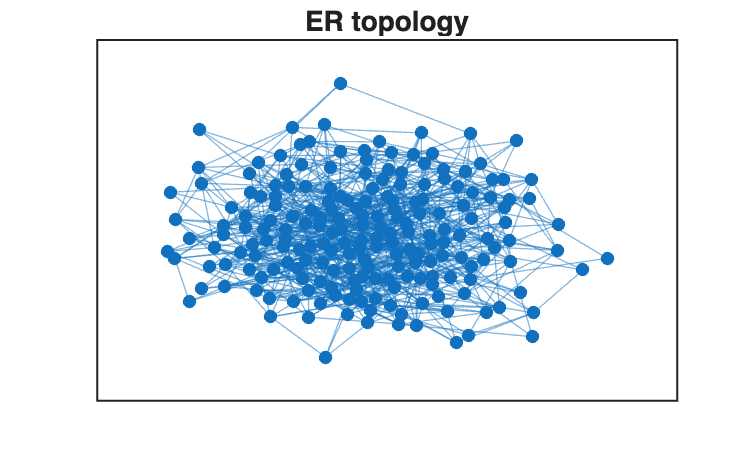

A_er = rand(N) < p;
A_er = triu(A_er,1);
A_er = A_er + A_er.';
A_er = spones(A_er);
G1 = graph(A_er);
figure; plot(G1,'Layout','force','NodeLabel',{},'MarkerSize',4);title('ER topology');

##  (c) Build model & DS


params.mu   = mu;
params.b    = b;
params.beta = beta;
params.epsL = epsL;

[MatA, MatB, MatF] = build_model_facilitation(A_er, params);
DS = DynamicalSystem(1);
DS.A = MatA; DS.B = MatB; DS.fnl = MatF;
DS.Options.Emax = 2;
DS.Options.Nmax = appr_order;
DS.Options.notation = 'tensor';
DS.Options.sigma = 1000;

## (d) Leading mode & initial condition

[V,~,~] = DS.linear_spectral_analysis();


 The first 2 nonzero eigenvalues are given as 
    0.6770
    0.4856



q0      = q0_mag * sign(V(1,1));
z0_full = q0 * V(:,1);

## (e) Full system trajectory 

[tRef, zRef] = time_integration_transient(DS, 2*pi, ...
    'nSteps', nsteps/tf, 'nCycles', tf, ...
    'integrationMethod','ode45', 'outdof', 1:N, 'init', z0_full);

## (f) SSM trajectories

traj_all = cell(numel(orders),1);
R0_for_analytic = [];
for k = 1:numel(orders)
    ord = orders(k);
    S   = SSM(DS);
    S.Options.paramStyle = 'graph';
    S.Options.reltol     = 100;
    S.Options.notation   = 'tensor';
    S.choose_E(1);
    [W0, R0] = S.compute_whisker(ord);
    if ord == appr_order, R0_for_analytic = R0; end
    traj_all{k} = transient_traj_on_auto_ssm( ...
                     DS, 1, W0, R0, tf, nsteps, 1:N, [], q0);
end

sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.15E-01 MB


sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.15E-01 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.28E-01 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.38E-01 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.50E-01 MB
Computing autonomous whisker at order 6
1 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 1.64E-01 MB
Computing autonomous whisker at order 7
1 (near) inner resonance(s) detecte

sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.15E-01 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.28E-01 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.38E-01 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.50E-01 MB
Computing autonomous whisker at order 6
1 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 1.64E-01 MB
Computing autonomous whisker at order 7
1 (near) inner resonance(s) detecte

sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.15E-01 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.28E-01 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.38E-01 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.50E-01 MB
Computing autonomous whisker at order 6
1 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 1.64E-01 MB
Computing autonomous whisker at order 7
1 (near) inner resonance(s) detecte

## (g) Node-level dynamics

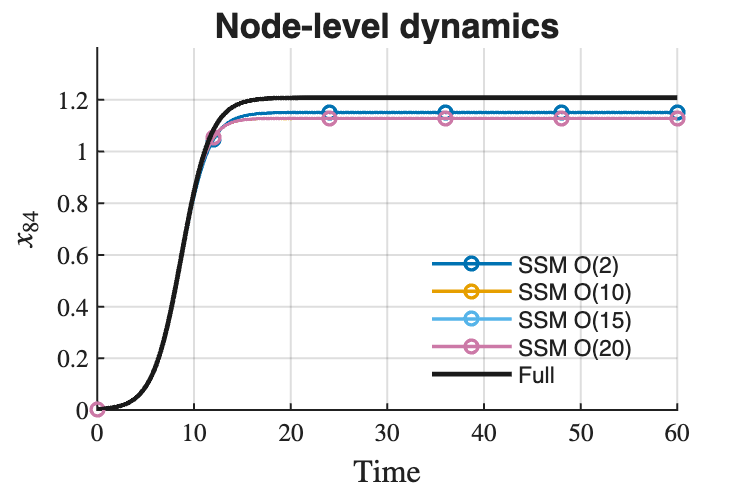

rng(1); idnode = randi(N);
figN = figure('Color','w','Position',[120 120 640 420]);
axN  = axes(figN); hold(axN,'on');

for k = 1:numel(orders)
    c = Style.ColSSM(k,:);
    tk = traj_all{k}.time;
    xk = traj_all{k}.phy(:,idnode);
    plot(axN, tk, xk, '-', ...
        'Color', c, 'LineWidth', Style.LW_ssm, ...
        'Marker', Style.MarkersSSM{k}, ...
        'MarkerIndices', 1:max(1,round(numel(tk)/5)):numel(tk), ...
        'MarkerSize', 4.8, ...
        'DisplayName', sprintf('SSM O(%d)', orders(k)));
end

plot(axN, tRef, zRef(:,idnode), '-', ...
     'Color', Style.ColFull, 'LineWidth', Style.LW_full, ...
     'DisplayName','Full');

xlabel(axN, 'Time', 'FontSize',Style.LabelFS,'Interpreter','latex');
ylabel(axN, sprintf('$x_{%d}$',idnode), ...
       'FontSize',Style.LabelFS,'Interpreter','latex');
set(axN,'TickLabelInterpreter','latex','LineWidth',Style.AxisLineWidth);
title(axN, 'Node-level dynamics','FontSize',Style.TitleFS);
legend(axN,'Location','best','Box','off');
grid(axN,'on');

## (h) Mean dynamics 

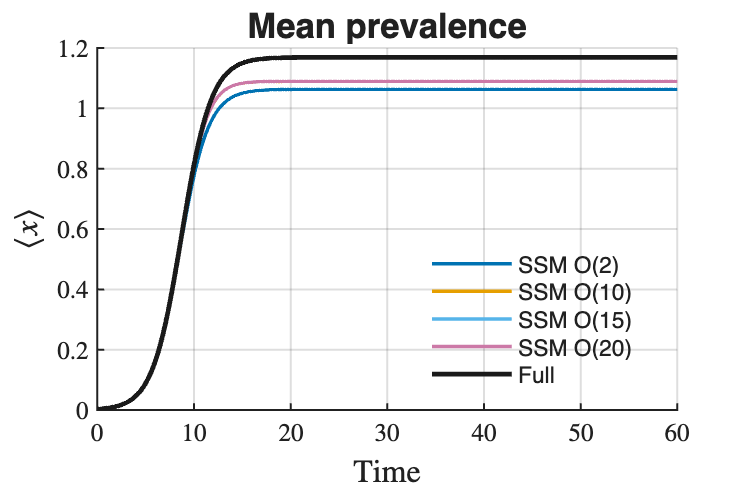

figM = figure('Color','w','Position',[140 140 640 420]);
axM  = axes(figM); hold(axM,'on');
for k = 1:numel(orders)
    tk = traj_all{k}.time;
    mk = mean(traj_all{k}.phy,2);
    plot(axM, tk, mk, '-', ...
        'Color', Style.ColSSM(k,:), 'LineWidth', Style.LW_ssm, ...
        'DisplayName', sprintf('SSM O(%d)', orders(k)));
end
t_full = tRef(:);
m_full = mean(zRef,2);
plot(axM, tRef, m_full, '-', ...
     'Color', Style.ColFull, 'LineWidth', Style.LW_full, ...
     'DisplayName','Full');

xlabel(axM, 'Time', 'FontSize',Style.LabelFS,'Interpreter','latex');
ylabel(axM, '$\langle x\rangle$', ...
       'FontSize',Style.LabelFS,'Interpreter','latex');
set(axM,'TickLabelInterpreter','latex','LineWidth',Style.AxisLineWidth);
title(axM, 'Mean prevalence','FontSize',Style.TitleFS);
legend(axM,'Location','best','Box','off');
grid(axM,'on');

##  (i) Analytical domain

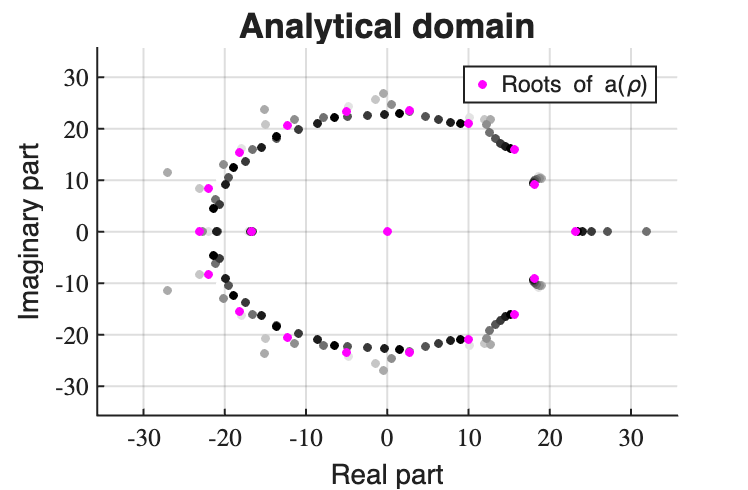

figA = figure('Color','w','Position',[160 160 640 420]);
axA  = axes(figA); hold(axA,'on');

plot_analytical_domain(appr_order, R0_for_analytic);

set(axA,'TickLabelInterpreter','latex','LineWidth',Style.AxisLineWidth);
title(axA, 'Analytical domain','FontSize',Style.TitleFS);
grid(axA,'on');

##  (j) Local functions

function [A,B,F] = build_model_facilitation(adj, params)
    n    = size(adj,1);
    mu   = params.mu;
    b    = params.b;
    beta = params.beta;
    epsL = params.epsL;
    B = speye(n);
    A = mu*speye(n) + epsL*adj;  
    F2 = sptensor([],[],[n n n]);
    idx  = (1:n).';
    subs_loc = [idx, idx, idx];
    vals_loc = -b*ones(n,1);
    F2 = F2 + sptensor(subs_loc, vals_loc, [n n n]);
    [ii,jj] = find(adj);
    if ~isempty(ii)
        subs_cross = [ii, ii, jj];
        vals_cross =  beta * ones(numel(ii),1);
        F2 = F2 + sptensor(subs_cross, vals_cross, [n n n]);
    end
    F = {F2};
end

function apply_pub_defaults(S)
    set(groot,'defaultAxesFontName',S.FontName);
    set(groot,'defaultAxesFontSize',S.BaseFS);
    set(groot,'defaultAxesLineWidth',S.AxisLineWidth);
    set(groot,'defaultAxesTickDir','out');
    set(groot,'defaultAxesBox','off');
end

function name = pick_font(primary, fallback)
    f = listfonts; name = fallback;
    if any(strcmpi(f, primary)), name = primary; end
end

**Note:**

For computing quantitative error metrics such as time-to-steady-state error, node-level MAE, spatial correlation, and mean-prevalence MSE, one can directly implement the procedure provided in the accompanying file **SIS_demo.mlx**, which illustrates the complete computation pipeline.